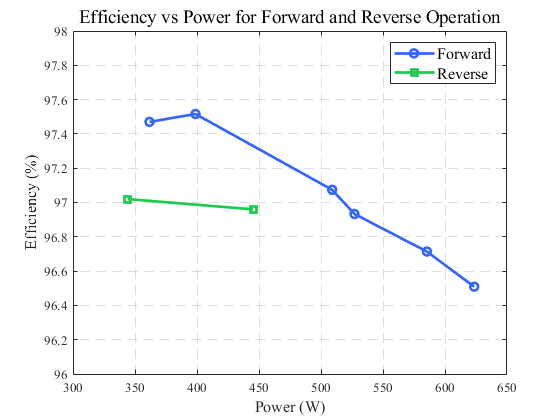

% 定义正向和反向数据
% 正向数据（电池端口到DC bus）
power_forward = [623.5, 585.4, 527, 509, 398.795, 361.7];
efficiency_forward = [96.509, 96.714, 96.933, 97.074, 97.516, 97.470];

% 反向数据（DC bus到电池端口）
power_reverse = [344.189, 445.287];  % 反向功率取负值
efficiency_reverse = [97.02, 96.96];

% 创建图形窗口
figure;

% 绘制正向数据
plot(power_forward, efficiency_forward, '-o', 'DisplayName', 'Forward', 'LineWidth', 2, 'MarkerSize', 6, 'Color', [0.2, 0.4, 1]); % 蓝色

hold on;

% 绘制反向数据
plot(power_reverse, efficiency_reverse, '-s', 'DisplayName', 'Reverse', 'LineWidth', 2, 'MarkerSize', 6, 'Color', [0.1, 0.8, 0.3]); % 绿色

% 设置坐标轴标签
xlabel('Power (W)', 'FontSize', 12, 'FontName', 'Times New Roman');
ylabel('Efficiency (%)', 'FontSize', 12, 'FontName', 'Times New Roman');

% 设置坐标轴范围
xlim([300, 650]); % 包含反向功率（-600 到 -300）和正向功率（300 到 650）
ylim([96, 98]); % 根据效率范围，设定纵坐标范围为96%到98%

% 打开网格并设置网格线为虚线
grid on;
set(gca, 'GridLineStyle', '--'); % 网格线设置为虚线

% 添加图例
legend('Location', 'northeast', 'FontSize', 12, 'FontName', 'Times New Roman');

% 设置字体为新罗马字体
set(gca, 'FontName', 'Times New Roman');

% 显示图形
hold off;